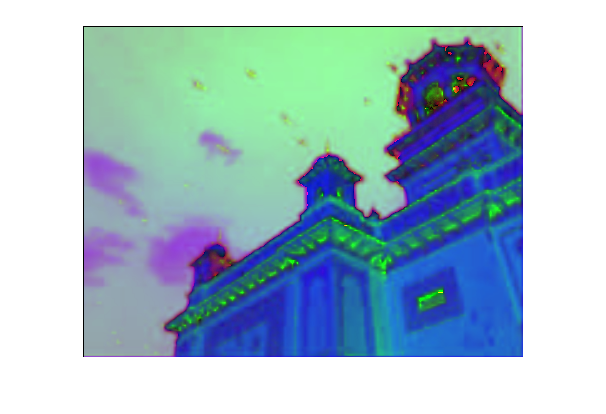

img = imread("zdjecie.PNG");
hsv_255 = rgb2hsv_custom(img);

[XX, YY, ~] = size(hsv_255);

hist2d = zeros(180, 256);  % y = Hue (0–179), x = Saturation (0–255)
imshow(rgb2hsv(img))

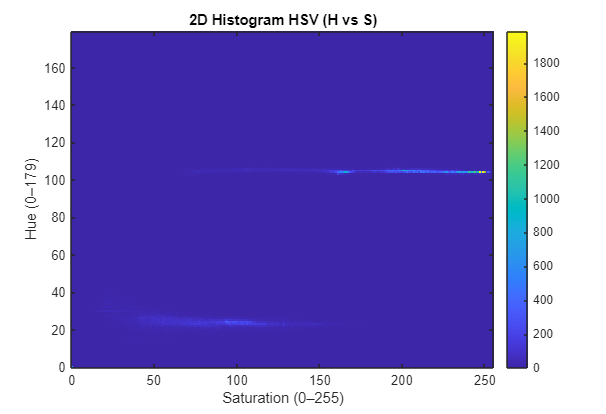

for x = 1 : XX
    for y = 1 : YY
        hue = int32(hsv_255(x, y, 1));       % już w zakresie 0–180
        sat = int32(hsv_255(x, y, 2));       % już w zakresie 0–256

        hist2d(hue + 1, sat + 1) = hist2d(hue + 1, sat + 1) + 1;
    end
end

% Wyświetlenie histogramu
imagesc(0:255, 0:179, hist2d);  % Oś X = Saturation, Y = Hue
xlabel('Saturation (0–255)');
ylabel('Hue (0–179)');
title('2D Histogram HSV (H vs S)');
colorbar;
axis xy;  % poprawna orientacja osi

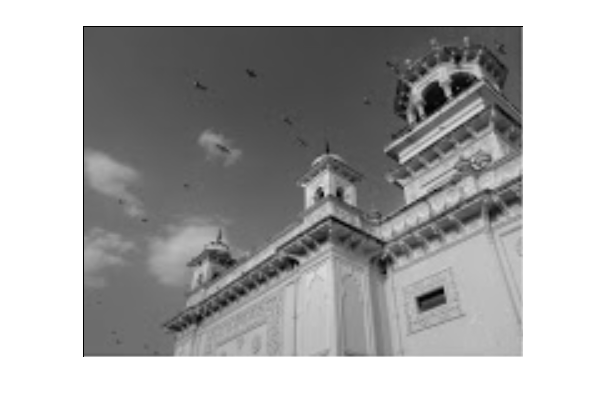

imshow(rgb2gray(img))



function hsv_custom = rgb2hsv_custom(img_rgb)
    img_rgb = im2double(img_rgb);
    
    R = img_rgb(:,:,1);
    G = img_rgb(:,:,2);
    B = img_rgb(:,:,3);
    
    Cmax = max(img_rgb, [], 3);
    Cmin = min(img_rgb, [], 3);
    delta = Cmax - Cmin;
    
    H = zeros(size(R));
    mask = delta ~= 0;
    
    idx = (Cmax == R) & mask;
    H(idx) = mod(60 * (G(idx) - B(idx)) ./ delta(idx), 360);
    
    idx = (Cmax == G) & mask;
    H(idx) = mod(60 * ((B(idx) - R(idx)) ./ delta(idx)) + 120, 360);
    
    idx = (Cmax == B) & mask;
    H(idx) = mod(60 * ((R(idx) - G(idx)) ./ delta(idx)) + 240, 360);
    
    H(~mask) = 0;
    H = H / 2;  % 0–180

    S = zeros(size(R));
    S(Cmax ~= 0) = delta(Cmax ~= 0) ./ Cmax(Cmax ~= 0);
    S = S * 255;  % 0–255
    
    V = Cmax;

    hsv_custom = cat(3, H, S, V);
end
